clc, clear;

syms f_1(x)
syms f_2(x)
f_1(x) = x^10-1;
f_2(x) = 1/(10*x^2+1);

% x = linspace(-1,1,20);
% [c_1, kappa_1] = interpolate(x, f_1)
% [c_2, kappa_2] = interpolate(x, f_2)

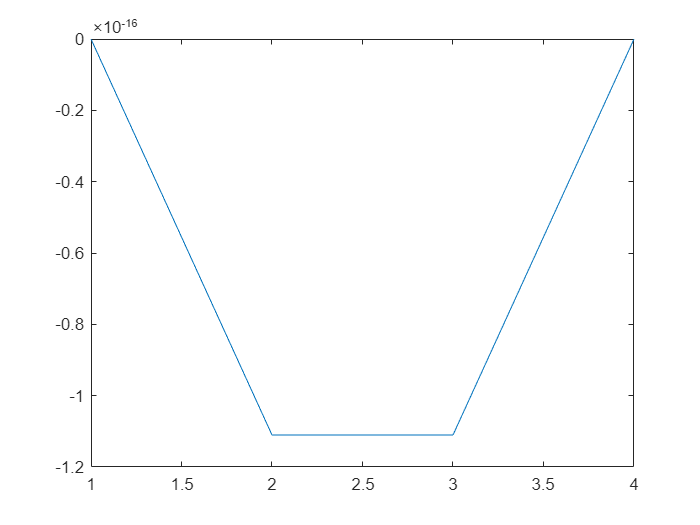

prox =          0   -1.0000   -1.0000         0


orig =          0   -1.0000   -1.0000         0


%syms x
%cheby = chebyshevT(0:50, x);

Z = []; % Roots of the cheby polynomial for k=2:2:100

% for k=[2:2:100]
%     row = zeros(1,100);
%     for l=1:k
%         row(l) =  cos(pi*(2*l-1)/(2*k));
%     end
%     Z = [Z; row];
%     
%     row
% end

C_1 = zeros(50,100);
error = zeros(1,50);
hold off
%fplot(f_1(x), [-1,1])
for n = 2:2:10
    points = linspace(-1,1,n);
    [C_1(n/2, 1:n), ~] = interpolate(points, f_1);
end

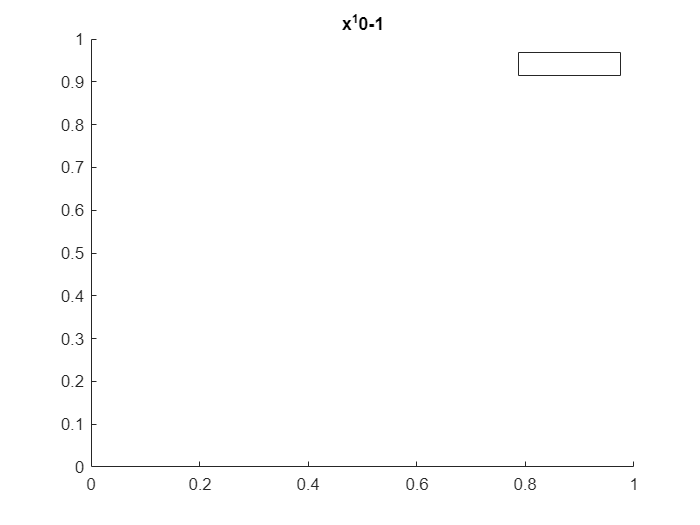

% syms y_1(x)
% y_1(x) = 0;
% for i=1:size(c_1,1)
%     y_1(x) = y_1(x) + c_1(i,1)*phi(i);
% end


figure;
title('x^10-1')
hold on;
%fplot(f_1(x), [-1,1], 'DisplayName', 'original')
%fplot(y_1(x),[-1,1], 'DisplayName', 'approximation')
legend('show')

syms x
phi = chebyshevT((0:size(c_2,1)-1), x);

Unrecognized function or variable 'c_2'.


syms y_2(x)
y_2(x) = 0;
for i=1:size(c_2,1)
    y_2(x) = y_2(x) + c_2(i,1)*phi(i);
end


figure;
title('1/(10*x^2+1)')
hold on;
%fplot(f_2(x), [-1,1], 'DisplayName', 'original')
%fplot(y_2(x),[-1,1], 'DisplayName', 'approximation')
legend('show')